# Rec 9 Post Probs

## 12.3.1

FundamentalFrequency = 784;
NinthHarmonicFrequency = FundamentalFrequency*9;
NyquistFrequnecy = NinthHarmonicFrequency*2

NyquistFrequnecy = 14112

## 12.3.11

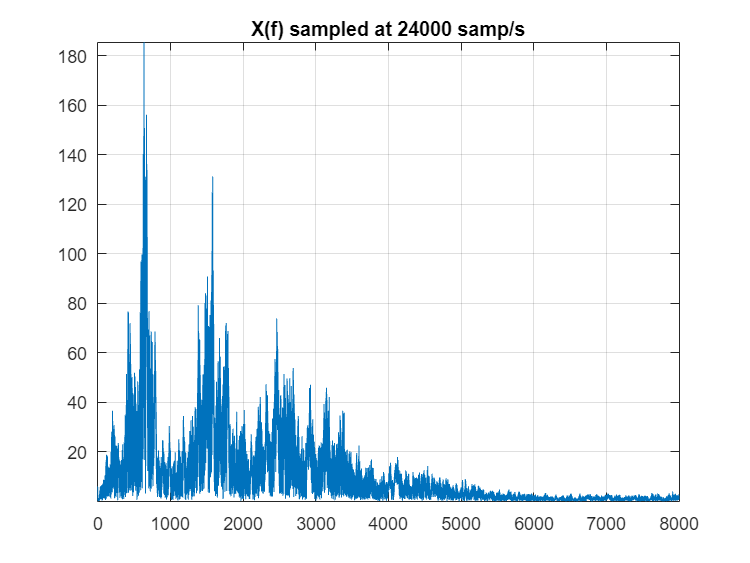

% a clear sound saying "MATLAB BREAKFAST OF CHAMPIONS"
load P673.mat; soundsc(X,24000);
% b
% file: e6_13_sound_alaised2.m
N=length(X)/3; 
F=linspace(0,8000,N); 
FX=abs(fft(X)); 
figure, plot(F,FX(1:N)), grid on, axis tight, title('X(f) sampled at 24000 samp/s');

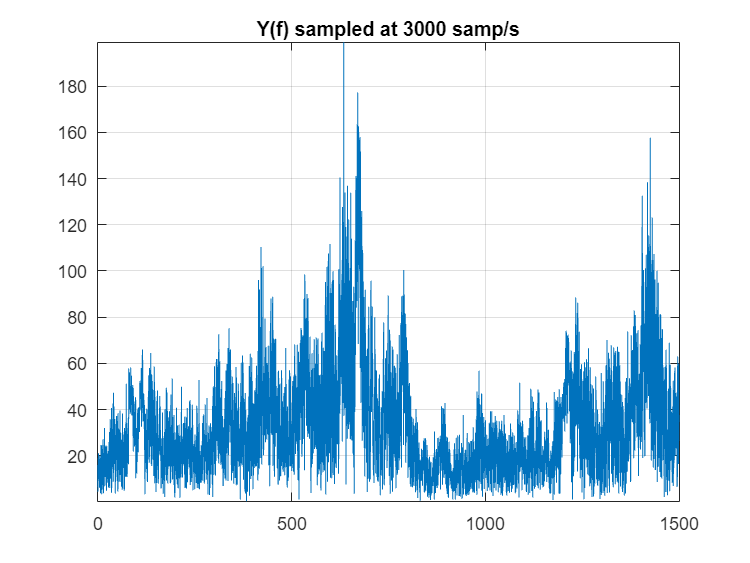

% c very muffled sound saying "MATLAB BREAKFAST OF CHAMPIONS".  Clearly a
% lot fuzzier and the frequency spectrum maintains the general shape of the
% audio signal but there is a lot more noise in the 0 - 80 range which
% comes through as muffling in the recording
Y=X(1:8:end); soundsc(Y,3000);  % reduce the sampling rate to 3000 samples/s
% display 1.5 kHz of frequency spectrum
N=length(Y)/2; 
F3=linspace(0,1500,N); 
FY=8*abs(fft(Y)); 
figure, plot(F3,FY(1:N)), grid on, axis tight, title('Y(f) sampled at 3000 samp/s');